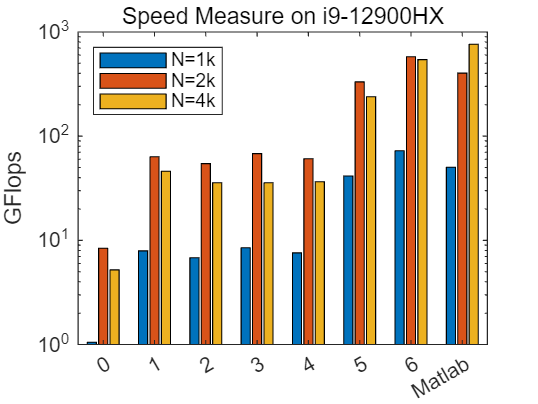

Time1k = [0.229796;
0.043154;
0.037065;
0.031924;
0.034419;
0.007962;
0.007007;0.017011];

Time2k = [1.902727;
0.252489;
0.293857;
0.235492;
0.263778;
0.048274;
0.027653;0.039786];
Time4k = [24.561001;
2.781965;
3.583504;
3.580928;
3.505939;
0.535964;
0.236099;0.168062];
bar([2*1e3^3./Time2k,2*2e3^3./Time2k,2*4e3^3./Time4k]./1e9)
set(gca, 'XTickLabel',{0,1,2,3,4,5,6,'Matlab'})
set(gca,'YScale','log')
legend('N=1k','N=2k','N=4k',Location='northwest')
ylabel('GFlops')
title('Speed Measure on i9-12900HX')

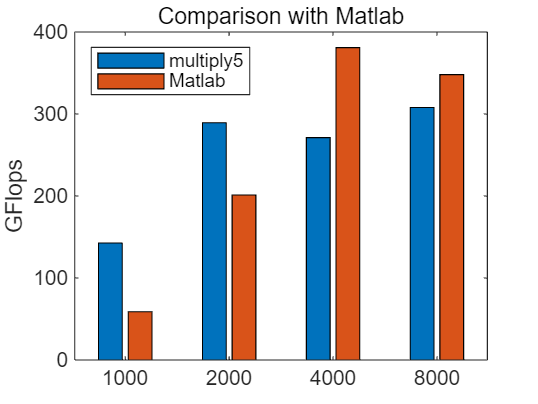

timeVSMatlab = [0.007007,0.017011;
 0.027653,0.039786;
 0.236099,0.168062;
  1.662961,1.471775];
matSize = repmat([1;2;4;8]*1e3,1,2);
bar(matSize.^3./timeVSMatlab/1e9)
set(gca, 'XTickLabel',[1;2;4;8]*1e3)
legend('multiply5','Matlab',Location='northwest')
ylabel('GFlops')
title('Comparison with Matlab')